# Primer Examen Parcial

# Primavera 2022

Sube tu archivo resultado (con las respuestas visibles) a Canvas $\to$ Examen Parcial 1 antes de las 9:55 horas.

Cada pregunta vale 5 puntos.

Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. 

El artículo 29 del Reglamento de Alumnos establece que "se calificará como no acreditada (N.A.) cualquier materia cuando el alumno incurra en alguna práctica fraudulenta".

Recuerda salvar frecuentemente tu archivo.

Puede ser conveniente limpiar periódicamente el espacio de trabajo (comando clear).

En el caso extremo de gráficas que aparecen mal, puedes salir y volver a entrar a la sesión.

## Pregunta 1.

¿Qué número real *x* está representado en punto flotante de doble precisión por la siguiente cadena hexadecimal?

hex = '3fe921fb54442d18';   % estándar IEEE 754
bin = '0011111111101001001000011111101101010100010001000010110100011000';

Extrae los diferentes campos del número binario *bin*

s = bin(1)

s = '0'

exp = bin(2:12)

exp = '01111111110'

m = bin(13:64)

m = '1001001000011111101101010100010001000010110100011000'

Calcula el signo *s (*-1 o 1)

sig = ((-1)^s)

sig = 1

Calcula el exponente con bias *be*

be = bin2dec(exp)

be = 1022

Calcula el exponente *e*

e = be - 1023

e = -1

Calcula la mantisa $f<1$

man = bin2dec(m) + 1 

man = 2.5706e+15

Calcula el número real *x* 

x1 = (sig)*(2^e)*(man)

x1 = 1.2853e+15

## Pregunta 2.

Observa el resultado de la siguiente expresión. 

res = (7/100)*100 - 7

res = 8.8818e-16

¿Por qué *res* no es igual a 0?

% Porque en Matlab utiliza eps para representar valores muy pequeños
% Y al restarle 7 lo que esta haciendo es mostrar eps(7)

Encuentra n tal que res = eps(n) y verifica tu respuesta usando la función de MATLAB *isequal*

e = eps(7)

e = 8.8818e-16

isequal(res, e)

ans = logical
   1


## Pregunta 3.

Calcula el error de la aproximación de la primera derivada centrada de cinco puntos 


$$f'(x) = \frac{ f(x-2h) - 8 f(x-h)  + 8 f(x+h) - f(x + 2h)}{12 h}$$


de la función$f\left(x\right)=\sin \left(x^2 \right)$ en el punto $x=2$ como función del espaciado *h *entre los valores de* x*. 

Calcula el valor exacto *dftrue* de la derivada de la función $f\left(x\right)=\sin \left(x^2 \right)$ en el punto $x=2$.

% f = @(x) sin(x.^2);
% fd = matlabFunction(diff(sym(f)));       % = @(x) 2*x.*cos(x.^2)
% x = 2;
% dftrue = fd(x)

Calcula el valor absoluto *te* del error para $h=\left\lbrack 1,{10}^{-1} ,{10}^{-2} ,{10}^{-3} ,\cdots ,{10}^{-9} \right\rbrack$.

Gráfica el valor absoluto del error *te* vs. *h* en una escala logarítmica (*loglog*)

Calcula el valor de h que debe usarse para tener la mejor exactitud.

Dado que el error de truncamiento de la aproximación es  $\frac{1}{30} f^{(5)}(\xi) h^4$, donde $\xi$ es un punto en el dominio, el error debería disminuir siempre que se reduzca *h*. Explica entonces ¿por qué aumenta el error al reducir *h* a partir del mínimo encontrado?

 %
 %

## Pregunta 4.

Resuelve la ecuación x=cos(x). 

La ecuación puede reformularse para encontrar las raíces de una función (anónima) *f1.*

f1 = @(x) x - cos(x);

Grafica  la función *f1 *en el intervalo [-2,2]

fplot(f1, [-2,2])

¿Cuántas raíces (ceros) tiene *f1*?

Encuentra una raíz de* f1* usando la función de MATLAB *fzero *y el valor inicial* x*=0.5. 

fzero(f1, 0.5)

ans = 0.7391

Encuentra una raíz de* f1* usando la función de MATLAB *fzero *y el valor inicial* x*=1. 

fzero(f1, 1)

ans = 0.7391

Resuelve la ecuación x=sin(x). 

Reformula la ecuación para encontrar las raíces de una función *f2*

f2 = @(x) x - sin(x);

Grafica  la función *f2 *en el intervalo [-2,2]

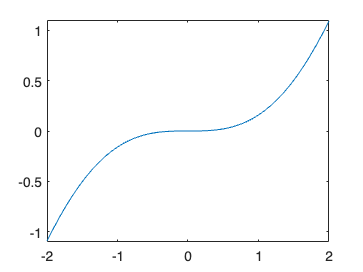

fplot(f2, [-2, 2]);

¿Cuántas raíces (ceros) tiene *f2*?

Encuentra una raíz de* f2* usando la función de MATLAB *fzero *y el valor inicial* x*=-0.5. 

fzero(f2, -0.5)

ans = 4.6469e-09

Encuentra una raíz de* f2* usando la función de MATLAB *fzero *y el valor inicial* x*=0. 

fzero(f2, 0)

ans = 0

Encuentra una raíz de* f2* usando la función de MATLAB *fzero *y el valor inicial* x*=0.5. 

fzero(f2, 0.5)

ans = -4.6469e-09

¿Cuántas raíces (ceros) tiene *f2*? ¿En qué puntos $\frac{\sin \left(x\right)}{x}=1$? Explica qué observas

% Tiene 1 raíz 
% Cuando sin(x)/ x vale 1, es decir sin(x) = x

## Pregunta 5.

Resuelve la ecuación $x^4 =2$. 

Reformula la ecuación para encontrar las raíces de una función *f*.

f4 = @(x) x.^4 - 2;

Grafica la función entre -1.5 y 1.5.

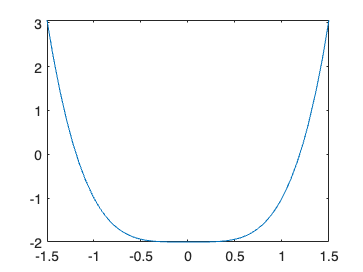

fplot(f4, [-1.5, 1.5])

Encuentra la raíz real positiva usando el método de Newton-Raphson y la aproximación inicial $x_0 =1$.

raiz = newtonRaphson(f4, 1, 3)

raiz = 1.1892

¿Para qué valor real $x_0$ el método no converge?

noraiz = newtonRaphson(f4, -1.5, 1.5)

noraiz = Inf

% Al parecer se acerca al cero pero nunca lo toca

## Pregunta 6.

Encuentra en qué valor de x ocurre el máximo de la función $f\left(x\right)=2\sin \left(x\right)-\frac{x^2 }{10}$ y cuál es el valor máximo, usando alguno de los métodos vistos en clase.

f = @(x) 2*sin(x) - x.^2/10

f = function_handle with value:
    @(x)2*sin(x)-x.^2/10


max = newtonOpt(@(x) -f(x), -1, 1)

max = 5.2671

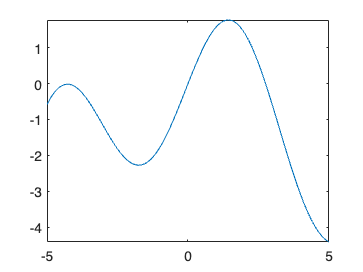

fplot(f)

Verifica tu solución usando la función de MATLAB *fminbnd*.

fminbnd(f(x))

Error using fminbnd (line 93)
The input to FMINBND should be either a structure with valid fields or consist of at least three arguments.

Encuentra la derivada *df* de la función $f\left(x\right)=2\sin \left(x\right)-\frac{x^2 }{10}$

df = matlabFunction(diff(sym(f)));

Encuentra en dónde vale cero *df *usando el algoritmo de Muller

cero = Muller(f, 0, 1 , 2)

## Pregunta 7.

Encuentra una fórmula para encontrar la siguiente aproximación en el método de interpolación parabólica sucesiva que calcula un punto crítico de una función *f*. Puedes usar el polinomio de interpolación de Lagrange (para obtener la fórmula del libro de texto) o el de Newton (para obtener la fórmula de la presentación del curso).

Inserta aquí una foto del procedimiento.

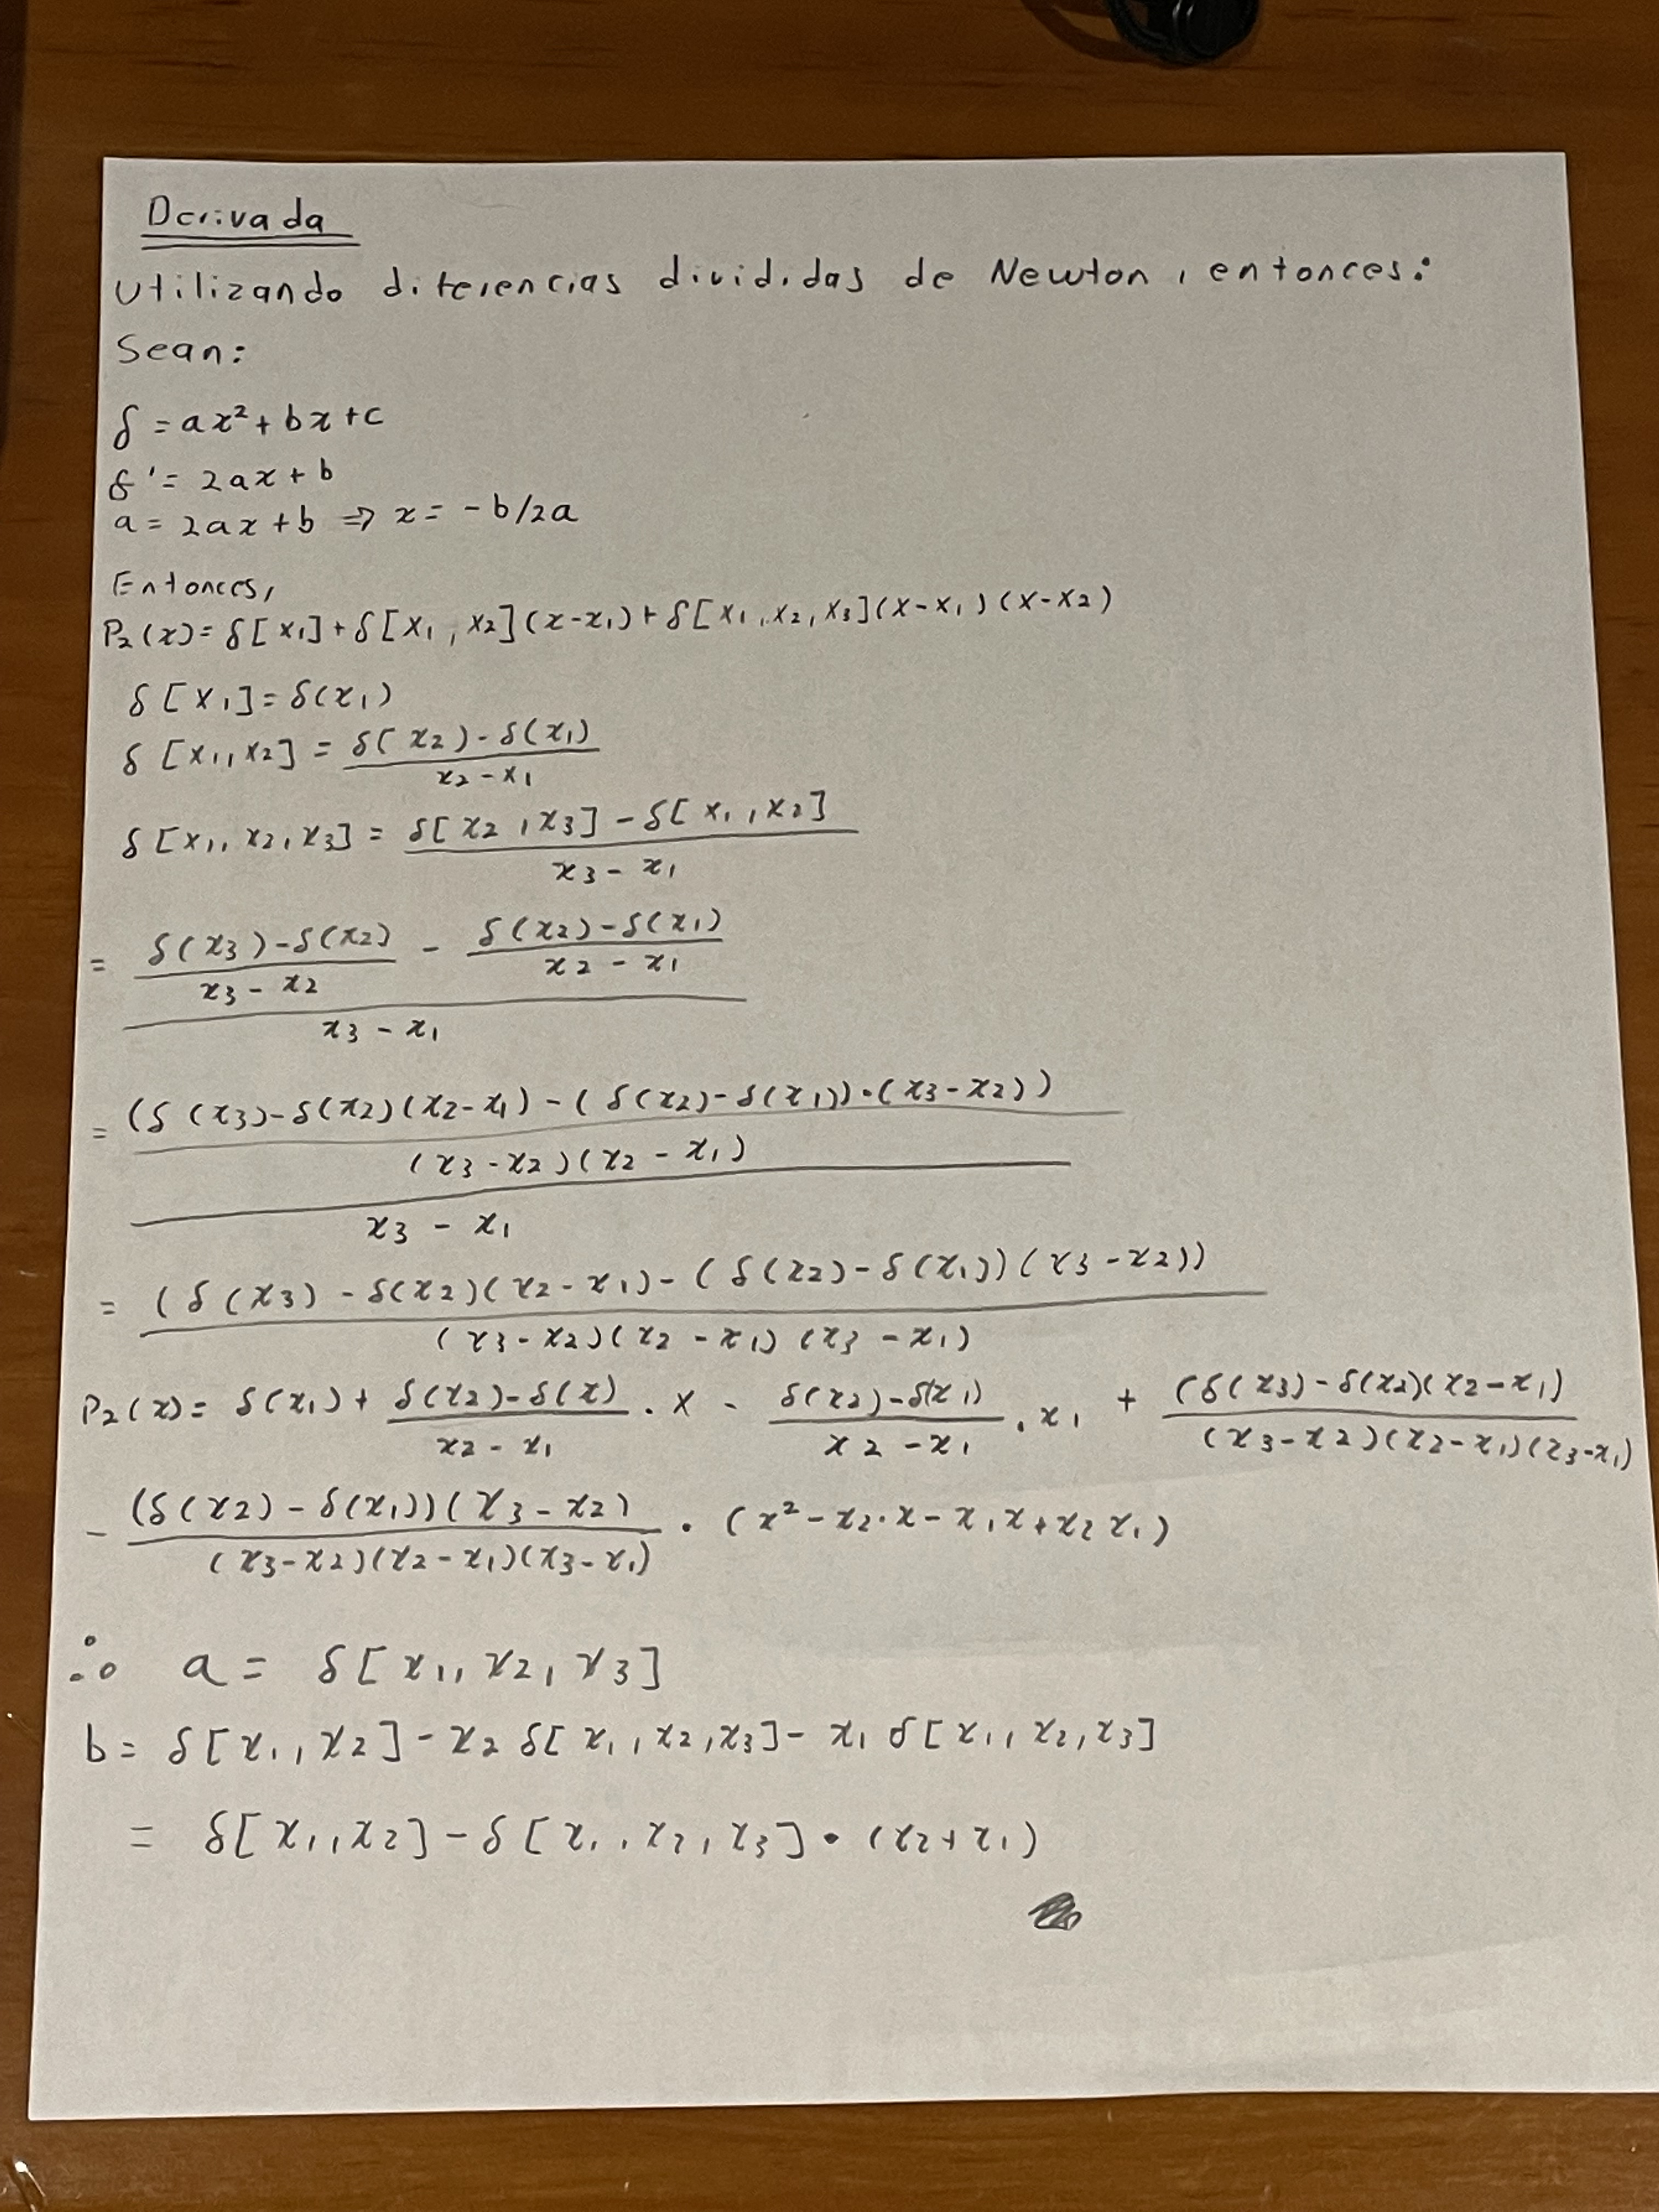

Escribe aquí las funciones que necesitas para correr el script.

## Pregunta 8.

Newton-Raphson

function [x, i] = newtonRaphson(f, a, b)
    REL_TOL = sqrt(eps);
    MAX_ITER = 53;
    x = (a + b) / 2;
    df = matlabFunction(diff(sym(f)));
    
    if nargin(df) == 0
        df = @(x) df();
    end
    
    i = 0;
    flag = true;
    while flag
        xp = x;
        dx = f(xp) / df(xp);
        x = xp - dx;
        i = i + 1;
        flag = i < MAX_ITER && abs(dx / x) > REL_TOL;     
    end
end

## Pregunta 9.

Método de optimización

function [x, i, m] = newtonOpt(f, a, b)
    TOL = eps;
    MAX_ITER = 53;
    x = (a + b) / 2;
    df = diff(sym(f));
    ddf = matlabFunction(diff(df));
    df = matlabFunction(df);
     
    if nargin(ddf) == 0
        ddf = @(x) ddf();
    end
    
    i = 0;
    flag = true;
    while flag
        xp = x;
        dx = df(xp) / ddf(xp);
        x = xp - dx;
        i = i + 1;
        flag = abs((dx / x)) > TOL && i < MAX_ITER;     
    end
    m = ddf(x) > 0;
end

## Pregunta 10.

Muller

function [x,i]= Muller(f,p1,p2,p3) 
    iMAX=52;
    TolMax=sqrt(eps);
    i=0;
    f1=f(p1);
    f2=f(p2);
    condition=true;
    while(condition)
        f3=f(p3);
        Pol2=polyfit([p1,p2,p3],[f1,f2,f3],2);
        r=roots(Pol2);
        if(abs(p3-r(1))<abs(p3-r(2)))
            x=r(1);
        else
            x=r(2);
        end
        f1=f2; f2=f3; 
        p1=p2; p2=p3; p3=x;
        i=i+1;
        condition=abs((x-p2)/x)>TolMax && i<iMAX;
    end
end